# 13주차 과제 — 상태궤환 극배치

**제어시스템설계** · 충남대학교 자율운항시스템공학과

문제는 **세 개**입니다.

- **1. 몸풀기** (쉬움 · 수업 중 10분 · 30점) — 극배치와 검증

- **2. 기본** (중간 · 40분 · 70점) — 사양에서 극점을 정하고 제어입력 확인

- **3. 도전** (선택 · 가산점 10점) — 거꾸로 선 진자를 세우기

**3번은 선택입니다.** 1번과 2번만 해도 만점입니다.

clc; close all;
s = tf('s');

## 1. 몸풀기 — 극배치 한 번 해 보기

**강의노트 2~3절을 그대로 보면 됩니다.**

아래 시스템의 극점을 $-3$ 과 $-4$ 에 놓는 $K$ 를 구하십시오.


$$A = \left[\begin{array}{cc} 0 & 1\\ -2 & -1\end{array}\right], \qquad B = \left[\begin{array}{c} 0\\ 1\end{array}\right]$$


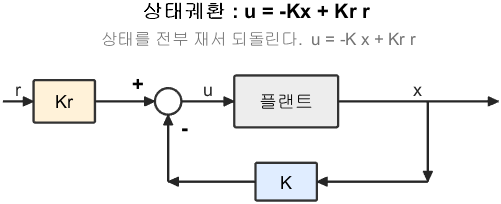

상태궤환 : u = -Kx + Kr r

**그림 파일** `loop_statefb.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_statefb')`

## 1-1. K 구하기

`TODO` 한 줄만 채우면 됩니다.

A1 = [0 1; -2 -1];
B1 = [0; 1];

K1 = NaN;
% TODO : K1 = place(A1, B1, [-3 -4]);  로 바꾸십시오

if isnan(K1)
    fprintf('  (아직 안 채웠습니다)\n');
else
    fprintf('  K = %s\n', mat2str(round(K1, 4)));
    fprintf('  검증 eig(A - B*K) = %s\n', ...
            mat2str(round(sort(eig(A1 - B1*K1)).', 4)));
end

## 1-2. 답할 것 (두 문장이면 됩니다)

- 개루프 고유값은 무엇이었습니까? (`eig(A1)`)

- 극배치를 하려면 무엇을 먼저 확인해야 합니까? 이 시스템은 그 조건을 만족합니까?

## 2. 기본 — 사양에서 극점을 정하고 제어입력까지 본다

**강의노트 4~7절을 보면 됩니다.**

DC 모터 위치제어에 다음 사양을 겁니다.

- 오버슈트 $10\%$ 이하

- 정착시간 $1.5$ 초 이하

- **구동기 한계 **$|u| \le 300$** V**

세 번째 조건이 오늘의 핵심입니다. 앞의 둘만 보면 답이 무한히 많지만, 세 번째를 넣으면 답이 좁아집니다.

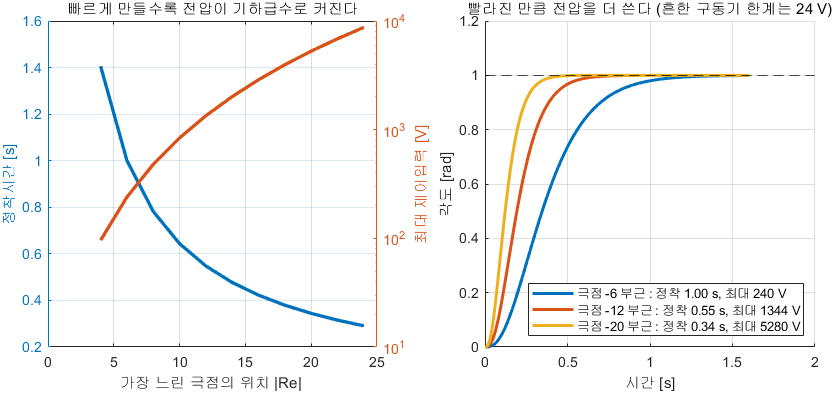

빨라진 만큼 전압을 더 쓴다

**그림 파일** `w13_effort.png` — `make_figures.m` 의 `fig_effort` · 다시 만들려면 `make_figures('w13_effort')`

## 2-1. 후보를 훑어 표 만들기

`TODO` 두 줄만 채우면 됩니다. 힌트 — `fsfb_design(sys, p_des)` 가 K, Kr, 그리고 제어입력까지 돌려줍니다.

[Gp, p] = plant_dcmotor('position');
sys = ss(p.A, p.B, p.C, p.D);

fprintf('\n     극점 위치        오버슈트[%%]   정착시간[s]   최대 u[V]   판정\n');
fprintf('   --------------  ------------  ------------  ----------  ------\n');
for a = 4:2:16
    p_des = [-a -a-2 -a-4];

    K = NaN;  info = [];
    % TODO : [K, Kr, info] = fsfb_design(sys, p_des);   로 바꾸십시오

    if isempty(info)
        fprintf('   %3.0f %3.0f %3.0f     (아직 안 채움)\n', p_des);
        continue
    end

    ok = false;
    % TODO : ok = (info.OS <= 10) && (info.ts <= 1.5) && (info.umax <= 300);

    fprintf('   %3.0f %3.0f %3.0f     %12.2f  %12.3f  %10.1f  %6s\n', ...
            p_des, info.OS, info.ts, info.umax, hw_yn(ok));
end

## 2-2. 고른 설계를 그림으로

**이 절은 코드가 다 되어 있습니다.** 위에서 고른 극점을 `a_pick` 에 넣고 실행만 하면 됩니다.

a_pick = 4;                      % <- 2-1 표에서 고른 값으로 바꾸십시오
[K, Kr, info] = fsfb_design(sys, [-a_pick -a_pick-2 -a_pick-4]);

tiledlayout(1, 2, 'TileSpacing', 'compact');
nexttile
plot(info.t, info.y, 'LineWidth', 2.4); grid on; yline(1, 'k--');
xlabel('시간 [s]'); ylabel('각도 [rad]');
title(sprintf('오버슈트 %.1f %%, 정착 %.3f s', info.OS, info.ts));
nexttile
plot(info.t, info.u, 'LineWidth', 2.4, 'Color', [0.85 0.2 0.15]); grid on;
yline(300, 'k--'); yline(-300, 'k--');
xlabel('시간 [s]'); ylabel('제어입력 [V]');
title(sprintf('최대 %.1f V (한계 300 V)', info.umax));

## 2-3. 답할 것 (다섯 문장이면 됩니다)

- 사양 세 가지를 **모두** 만족하는 극점은 어느 것들입니까?

- 그중 하나를 골랐다면 **왜 그것을 골랐는지** 쓰십시오

- 구동기 한계 조건을 빼면 어떤 극점까지 쓸 수 있습니까?

- 극을 왼쪽으로 보낼 때 정착시간과 제어입력 중 **무엇이 더 빨리 변합니까?**

- **추가 질문** — 정착시간 사양을 $0.8$ 초로 조이면 합격하는 조합이 있습니까? 없다면 그때는 무엇을 해야 합니까? (선택지를 두 가지만 적으면 됩니다)

## 3. 도전 (선택) — 거꾸로 선 진자를 세우기

**강의노트 9~11절을 보면 됩니다.** 안 해도 감점 없습니다.

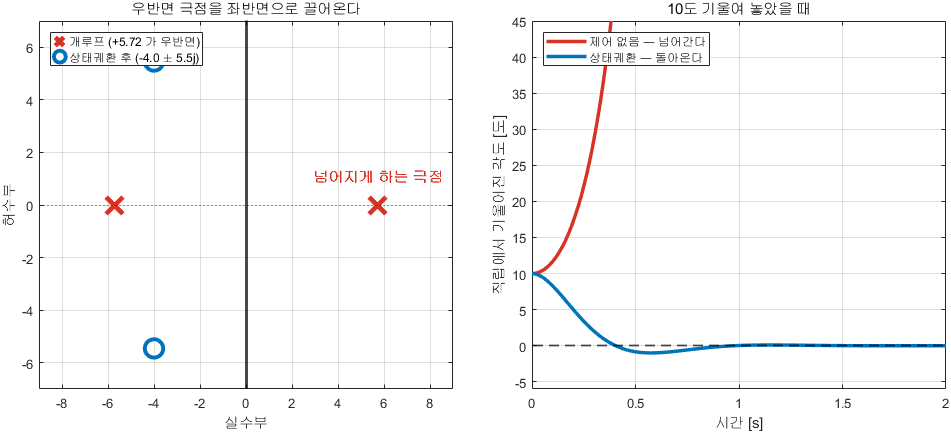

우반면 극점을 좌반면으로 끌어온다

**그림 파일** `w13_pendulum.png` — `make_figures.m` 의 `fig_w13_pendulum` · 다시 만들려면 `make_figures('w13_pendulum')`

할 일

- `plant_pendulum(pi)` 로 거꾸로 선 진자의 선형 모델을 얻으십시오

- 개루프 고유값을 확인하십시오. 어느 것이 문제입니까?

- 오버슈트 $10\%$, 정착시간 $1.5$ 초 사양으로 극점을 정하고 $K$ 를 구하십시오

- $10$ 도 기울인 채로 놓았을 때의 응답을 그리십시오

- **가장 중요한 부분** — 필요한 최대 토크를 구하고, 모터가 $0.5$ Nm 까지만 낼 수 있다면 어떻게 되는지 쓰십시오

**좌표 주의** — 비선형 함수 `p.f` 는 매달린 자세 기준 **절대 각도**를 받고, 선형 모델 $(A, B)$ 는 직립 기준 **편차**입니다. 섞어 쓰면 안 됩니다. 비선형으로 검증하려면 아래처럼 좌표를 맞추십시오.

- 편차 `dx = [x(1) - pi; x(2)]`

- 제어입력 `u = pUp.u0 - K*dx`

- 초기조건 `x0 = [pi + deg2rad(10); 0]`

[sysUp, pUp] = plant_pendulum(pi);
fprintf('\n=== 3. 도전 문제 ===\n');
fprintf('  개루프 고유값 : %s\n', mat2str(round(eig(pUp.A).', 3)));
fprintf('  (여기서부터 직접 해 보십시오)\n');

## 4. 제출 방법

- 이 파일을 `W13_HW_학번_이름.mlx` 로 저장해 제출하십시오

- `TODO` 를 채운 코드와 **실행 결과(그림 포함)** 가 함께 보여야 합니다

- 답할 것은 각 문제 아래에 **글로 적으십시오**. 한두 문장이면 충분합니다

- 도전 문제를 안 했으면 그 절은 그대로 두십시오

## 5. 채점 기준

- **1. 몸풀기** 30점 — $K$ 를 구했는가, 가제어를 먼저 확인해야 함을 썼는가

- **2. 기본** 70점 — 표를 채웠는가, 합격 조합을 골랐는가, 다섯 질문에 답했는가

- **3. 도전** 가산점 10점 — 진자를 세우고 토크 한계를 논했는가

감점 항목 (세 개뿐입니다)

- **제어입력을 확인하지 않은 경우.** 극배치는 공짜가 아닙니다

- $u = -Kx$ 의 부호를 반대로 쓴 경우

- 그림에 축 이름이나 범례가 없는 경우

---------------------------------------------------------------

function s = hw_yn(tf_)
if tf_, s = '합격'; else, s = '불합격'; end
end